## Problem 1

Consider the BVP on $[0, 1]$:


$$$$
-\frac{\mathrm{d}}{\mathrm{d} x}\left( \left(1 + x^2\right)\frac{\mathrm{d} u}{\mathrm{d} x}\right) = 2, \quad 0 < x < 1,\quad u(0) = 0,\quad u'(1) = -3.
$$$$


Use **one linear element** on $[0, 1]$, with nodes $x_{1} = 0$ and $x_{2} = 1$.

Let $\psi_{i}$ be the linear shape functions and write $u_{h}(x) = U_{1}\psi_{1}(x) + U_{2}\psi_{2}(x)$.

**Matlab is nor permitted for this exercise.** Select one answer per part. Numerical choices are rounded to five decimal places. An incorrect choice subtracts 25% of the points for the part. Select "Empty answer (no penalty)" to receive zero points without a penalty,

(a) (2 points) Compute $K_{11}$, the $(1,1)$ entry of the stiffness matrix $K$, before imposing boundary conditions.

- `1.33333 ✔️`

- `1.00000`

- `2.66667`

- `0.66667`

- Empty answer (no penalty)

**Solution**

The shape functions of the element and their derivatives are,


$$\begin{array}{ll}
\psi_{1} (x) = \frac{x - 1}{0-1} = 1-x, &
    \frac{\mathrm{d}\psi_{1}}{\mathrm{d} x}(x) = -1,\\
\psi_{2}(x) = \frac{x-0}{1-0} = x, & 
    \frac{\mathrm{d}\psi_{2}}{\mathrm{d} x}(x) = 1.
\end{array}$$


So the components of the stiffness matrix are,


$$\begin{array}{l}
K_{ij} = \int_{x_{1}}^{x_{2}} a_{1}(x) \frac{\mathrm{d}\psi_{i}}{\mathrm{d} x}(x)\frac{\mathrm{d}\psi_{j}}{\mathrm{d} x}(x)\,\mathrm{d} x =
\int_{0}^{1} \left(1 + x^{2}\right) \frac{\mathrm{d}\psi_{i}}{\mathrm{d} x}(x)\frac{\mathrm{d}\psi_{j}}{\mathrm{d} x}(x)\,\mathrm{d} x \\
\phantom{K_{ij}}  = (-1)^{i + j} \int_{0}^{1} \left(1 + x^{2}\right)\,\mathrm{d} x = (-1)^{i+ j}
\left[ x + \frac{x^{3}}{3}\right]_{x = 0}^{x = 1} = \frac{3}{4} (-1)^{i+j},\quad i, j = 1,2.
\end{array}$$


and them, the stiffness matrix is,


$$K = \left(\!\begin{array}{rr}
3 / 4 & -3/4\\
-3/4 & 3/4
\end{array}\!\right),$$


so $K_{11} = 3 / 4 \approx 1.33333$. 

We can check this result using Matlab:

clearvars
close all
syms x;
nodes = [0; 1];
h = nodes(2) - nodes(1);
a(x) = 1+x^2;
f = 2;
U0 = 0;
DU1 = -3;

$$K = \left(\begin{array}{cc} \frac{4}{3} & -\frac{4}{3}\\ -\frac{4}{3} & \frac{4}{3} \end{array}\right)$$

K(1,1) = 1.33333


Psi(x) = [nodes(2)-x, x-nodes(1)] / h;

K = int(1+x.^2,x,nodes(1),nodes(2)) * [1, -1; -1, 1] / h^2
fprintf("K(1,1) = %.5f\n", K(1,1))

$$F = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

F(1) = 1.00000

(b) (2 points) Compute the source load $F_{1}$.

- Empty answer (no penalty)

- `2.00000`

- `-1.00000`

- `1.00000 ✔️`

- `0.50000`

**Solution**

According to the derived formulas, the components the local source load vector, $F$, of the element are given by,


$$\begin{array}{r}
F_{i} = \int_{x_{1}}^{x_{2}} f(x)\psi_{i} (x)\,\mathrm{d}x,\quad i = 1, 2.
\end{array}$$


So,  for this case in point,


$$\begin{array}{l}
F_{1} = \int_{0}^{1} 2\left(1 - x\right)\,\mathrm{d}x = 2\left[ x - \frac{x^{2}}{2}\right]_{x = 0}^{x = 1} = 2 \times \frac{1}{2} = 1,\\
F_{2} = \int_{0}^{1} 2 x\,\mathrm{d} x = 2\left[\frac{x^{2}}{2}\right]_{x = 0}^{x = 1} = 2 \times \frac{1}{2} = 1.
\end{array}$$


Hence $F = \left(\!\begin{array}{c} 1\\ 1\end{array}\!\right)$, and $F_{1} = 1$. **Remark: **we note that in this case, as the source function is constant, $f(x)\equiv 2$, we can apply straight the formulas in the cheat-sheet and save the calculus of the above integrals. 

As before, we can check the gleaned result using Matlab:

F = int(f * Psi(x)',x,nodes(1),nodes(2))
fprintf("F(1) = %.5f", F(1))

(c) (4 points) Compute the FEM approximation using the given boundary conditions. Give the average of this nodal values, $\bar{U} = \left( U_{1} + U_{2} \right) / 2$.

- `-3.75000`

- `-0.93750`

- Empty answer (no penalty)

- `-1.87500 ✔️`

- `1.87500`

**Solution**

Using the previous results, we see that the system for the nodal values $U_{1}$ and $U_{2}$ casts,


$$$$
\left(\!\begin{array}{rr}
3 / 4 & -3/4\\
-3/4 & 3/4
\end{array}\!\right)
\left(\!\begin{array}{c}
U_{1}\\
U_{2}
\end{array}\!\right) = 
\left(\!\begin{array}{c}
1\\
1
\end{array}\!\right) +
\left(\!\begin{array}{c}
Q_{1}\\
Q_{2}
\end{array}\!\right) .
$$$$


Solving the system for the primary variables. **Note: **recall the $F$ was already computed in item (b)! so we need to allocate memory for vectors $u$ and $Q$. 

Q = zeros(2,1);
u = zeros(2,1);

$$Fm = -5$$


fixedNods = 1;
freeNods = 2;


u(1) = 0.00000
u(2) = -3.75000


%Boundary Conditions (B.C.):
% Natural
Q(2) = a(nodes(2))*DU1;

Averaged U = -1.87500

% Essential
u(1) = 0;

%Reduced system
Fm = Q(freeNods) + F(freeNods) - K(freeNods,fixedNods)*u(fixedNods)

$$\frac{15\,x}{4}-\log\left(x^{2}+1\right)-4\,\mathrm{atan}\left(x\right)$$

Km = K(freeNods,freeNods);

$$derr = \frac{15}{4}-\frac{4}{x^{2}+1}-\frac{2\,x}{x^{2}+1}$$

um = Km \ Fm;
u(freeNods) = um;
fprintf("u(1) = %.5f\nu(2) = %.5f\n", u(1), u(2));

$$15\,x^{2}-8\,x-1$$

Compute the average:

uBar = (u(1) + u(2)) / 2;

$$\left(\begin{array}{c} \frac{4}{15}-\frac{\sqrt{31}}{15}\\ \frac{\sqrt{31}}{15}+\frac{4}{15} \end{array}\right)$$

fprintf("Averaged U = %.5f", uBar)

**Solution:** $\bar{U} = -1.87500$.

## Question (d)

Exact solution $u(x) = -4\arctan(x) - \ln\left(1+x^2\right)$. We look for the absolute maximum of $\left|u(x) - u_{h}(x)$| at the closed interval $I = [0,1]$.

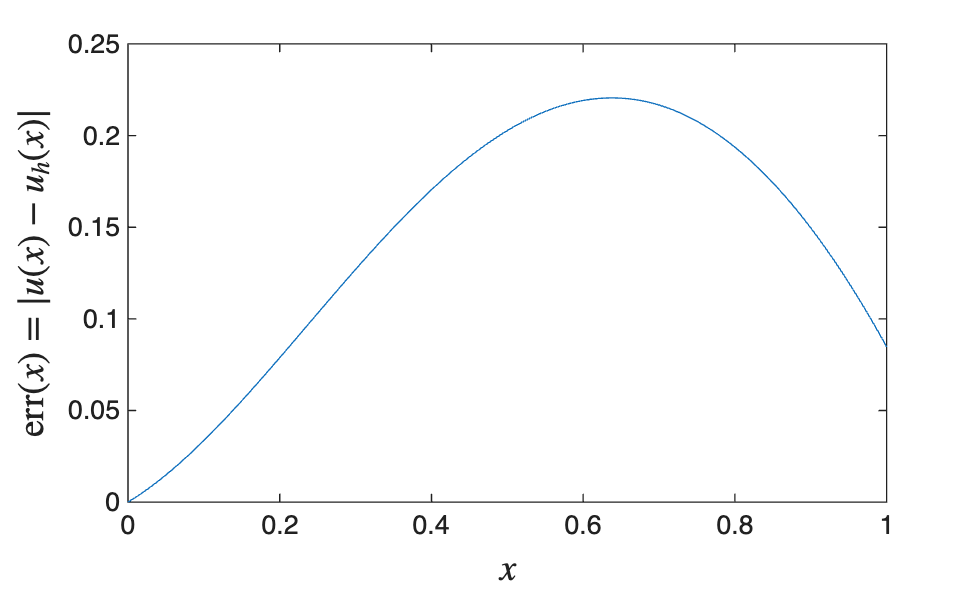

err(x) = - 4 * atan(x) - log(1+x.^2) - Psi(x) * u;

pretty(err(x))
derr = diff(err(x),x)

Valor màxim del error a l'interval [0,1], s'assoleix al punt x ≈ 0.63785


eqn = simplify(derr * 4*(x^2 + 1));
pretty(eqn)
sols = solve(eqn,x);
pretty(sols)
t = nodes(1):0.01:nodes(2);
errValues = double(err(t));
plot(t,abs(errValues),'-')
xlabel('$x$',Interpreter='LaTeX',FontSize=14)
ylabel('$\mathrm{err}(x) = |u(x)-u_{h}(x)|$',Interpreter='LaTeX', FontSize=14)
fprintf("Valor màxim del error a l'interval [%d,%d], s'assoleix al punt x %c %.5f", ...
    nodes(1),nodes(2), char(0x2248), double(sols(2)))

**Solution:** $\arg\max\limits_{0\le x \le 1} \left| u(x) - u_{h}(x)\right| = \frac{\sqrt{31}}{15} + \frac{4}{15} = 0.63785$.